# Fuzzy Systems - Assignment #1 - Arian Tashakkor - 40023494

## Problem 1

Let's assume $T(a, b) = min\{a,b\}$ and $S(a,b) = max\{a,b\}$:

### Proof of $T(a,b) = N(S(N(a), N(b)))$:

We know that $N(N(a)) = a$ so by applying $N$ to both sides, we will prove $N(T(a,b)) = S(N(a),N(b))$.

Without loss of generality, we can assume that $a\le b$ (because if $a>b$ then we can just set $b' = a$ and $a' = b$ and we still have $a' < b'$). With this assumption and applying $N$ to both sides of this inequality we have

$N(a)\ge N(b)$,

therefore $S(N(a), N(b)) = max\{N(a), N(b)\} = N(a)$. However, we also know that because $a \le b$,

$T(a, b) = min\{a, b\} = a$,

so we have

$N(T(a,b)) = N(a) = S(N(a), N(b))$.

### Proof of $S(a,b) = N(T(N(a), N(b)))$:

Again we will prove $N(S(a,b)) = T(N(a), N(b))$.

Using the same reasoning as the previous part, we can assume that $a \le b$. Applying $N$ to both sides of this we have

$N(a) \ge N(b)$,

therefore $T(N(a), N(b)) = min\{N(a), N(b)\} = N(b)$. However we also know that because $a\le b$,

$S(a,b)=max\{a,b\}=b$,

so we have

$N(S(a,b)))=N(b)=T(N(a),N(b))$.

## Problem 2


$$A = \{(x_1, 1), (x_3, 0.3)\}, \bar{A} = \{(x_2, 1), (x_3, 0.7), (x_4, 1)\}$$



$$B = \{(x_1,0.5), (x_2, 1), (x_3, 0.1), (x_4, 0.6)\}, \bar{B} = \{(x_1, 0.5), (x_3, 0.9), (x_4, 0.4)\}$$



$$C = \{(x_2, 0.2), (x_4, 0.2)\}, \bar{C} = \{(x_1, 1), (x_2, 0.8), (x_3, 1), (x_4, 0.8)\}$$


- 
$$A\cap B = \{(x_1, 0.5), (x_3, 0.1)\}$$


- 
$$A \cup C = \{(x_1, 1), (x_2, 0.2), (x_3, 0.3), (x_4, 0.2)\}$$


- 
$$B\cap C = \{(x_2, 0.2), (x_4, 0.2)\}$$


- 
$$\bar{B}\cap A = \{(x_1, 0.5), (x_3, 0.3)\}$$


- 
$$\bar{A}\cap A = \{(x_3, 0.3)\}$$


- 
$$\bar{C}\cup C = \{(x_1, 1), (x_2, 0.8), (x_3, 1), (x_4, 0.8)\}$$


## Problem 3

n_samples = 600;
domain = linspace(0, 60, n_samples);
mu_B = 1./(1 + ((domain - 30)/10).^4);

### A: Plot $\mu_B(x)$:

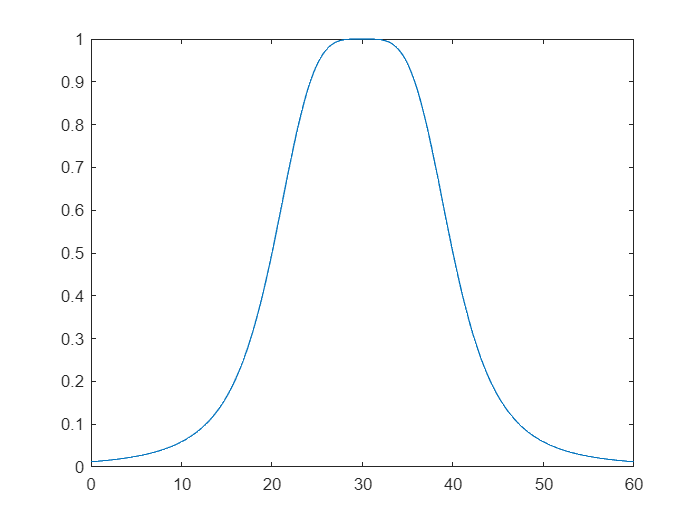

plot(domain,mu_B);
hold off

### B: Plot $Sup(B)$:

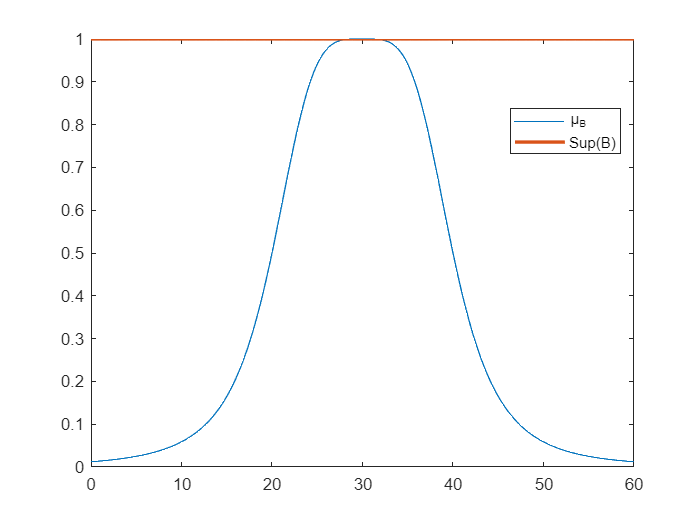

supp_B = (mu_B > 0);
plot(domain,mu_B);
hold on
plot(domain, supp_B, 'LineWidth', 2);
legend('\mu_B', 'Sup(B)', Location='best');
hold off

As we can see the entire domain belongs to $Sup(B)$.

### C: Calculate $hgt(B)$:

We know that $hgt(B) = max(\mu_B(x)) \le 1$. Considering that $\mu_B =  \frac{1}{1 + (\frac{x-30}{10})^4$ is precisely equal to 1 at $x=30$, we can say that $hgt(B) = 1$. 

### D: Is B normal?

$hgt(B) = 1$ which means there exists at least one $x$ for which $\mu_B(x) = 1$. This means that $Core(B)$is non-empty and therefore $B$ is normal. 

### E: Crossover points of B:

The crossover points of B are $x$ such that $\mu_B(x) = \frac{1}{2}$. Therefore, we solve this equation:

$\mu_B =  {\frac{1}{1 + (\frac{x-30}{10})^4} = \frac{1}{2} \rightarrow 1 + (\frac{x-30}{10})^4 = 2 \rightarrow (\frac{x-30}{10})^4 = 1 \rightarrow \frac{x-30}{10} = \pm 1$,

from which we can calculate two values for $x$:

$x_1: \frac{x_1 - 30}{10} = 1 \rightarrow x_1 = 40$,

$x_2:\frac{x_2 - 30}{10} = -1 \rightarrow x_2 = 20$.

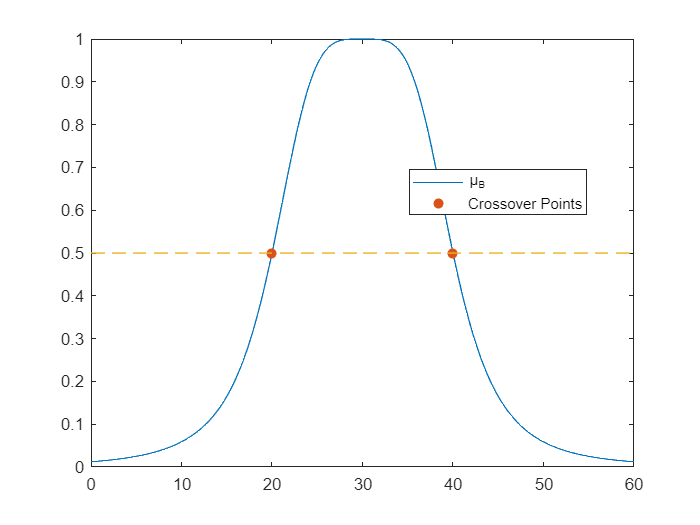

plot(domain,mu_B);
hold on
scatter([20, 40], [1./(1 + ((20 - 30)/10).^4), 1./(1 + ((40 - 30)/10).^4)], "filled");
hold on
plot(domain, 0.5*ones(1, n_samples), LineStyle="--");
legend('\mu_B', 'Crossover Points', 'Location','best');
hold off

### F: $\alpha$-cuts and strong $\alpha$-cuts for $\alpha = 0.25$ and $\alpha = 0.5$:

1. For $\alpha = 0.25$:

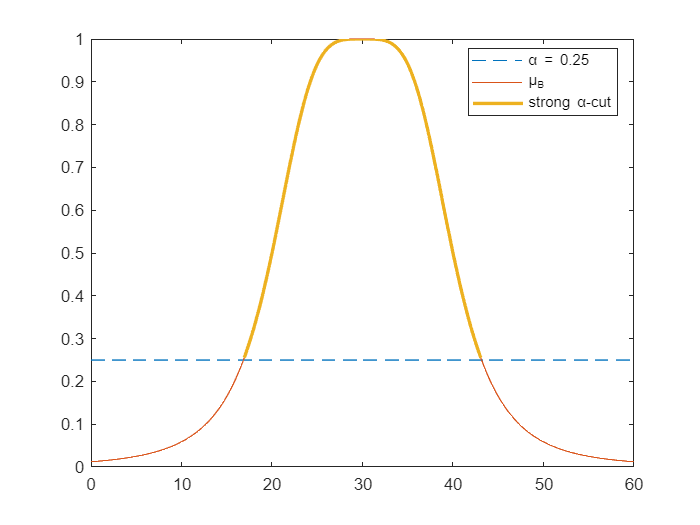

cut_0_25 = 0.25*ones(1,n_samples);
cut_strong = mu_B(mu_B>cut_0_25);
cut_weak = mu_B(mu_B>=cut_0_25);
plot(domain, cut_0_25, LineStyle="--");
hold on
plot(domain, mu_B);
hold on
plot(domain(mu_B>cut_0_25), cut_strong, 'LineWidth', 2);
legend('\alpha = 0.25', '\mu_B', 'strong \alpha-cut', 'Location','best');
hold off

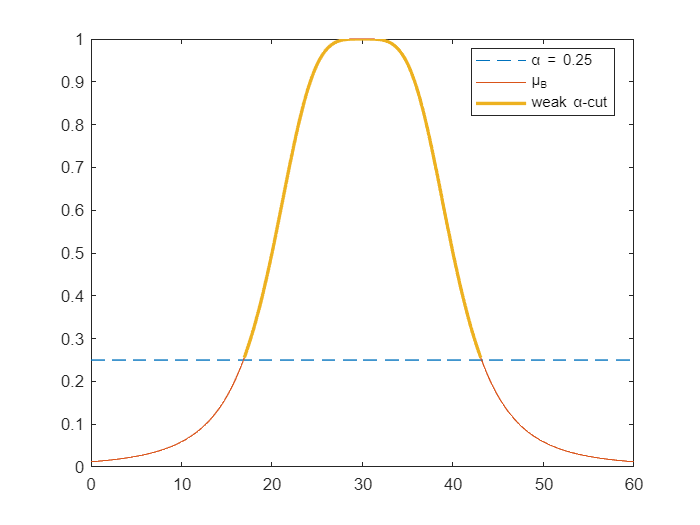

plot(domain, cut_0_25, LineStyle="--");
hold on
plot(domain, mu_B);
hold on
plot(domain(mu_B>cut_0_25), cut_weak, 'LineWidth', 2);
legend('\alpha = 0.25', '\mu_B', 'weak \alpha-cut', 'Location','best');
hold off

2. For $\alpha = 0.5$:

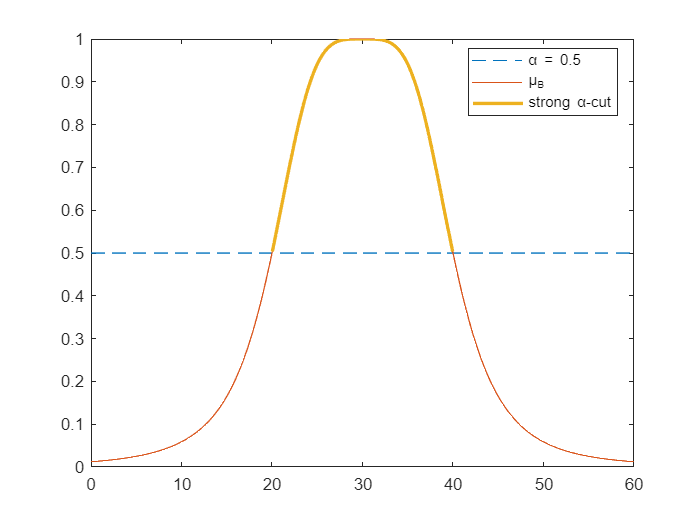

cut_0_5 = 0.5*ones(1,n_samples);
cut_strong = mu_B(mu_B>cut_0_5);
cut_weak = mu_B(mu_B>=cut_0_5);
plot(domain, cut_0_5, LineStyle="--");
hold on
plot(domain, mu_B);
hold on
plot(domain(mu_B>cut_0_5), cut_strong, 'LineWidth', 2);
legend('\alpha = 0.5', '\mu_B', 'strong \alpha-cut', 'Location','best');
hold off

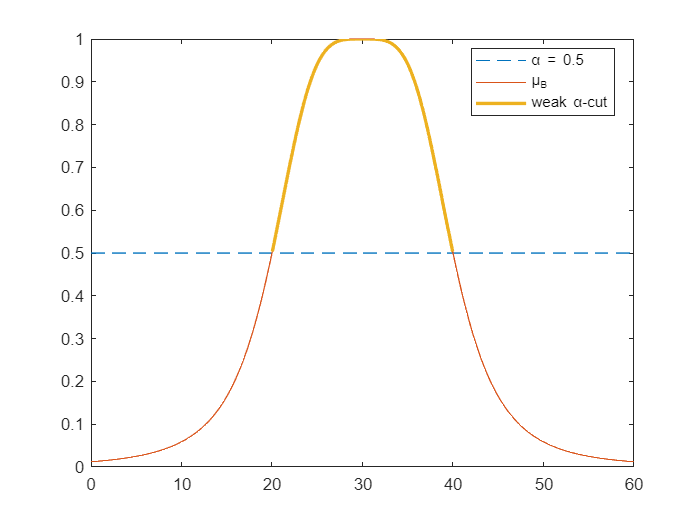

plot(domain, cut_0_5, LineStyle="--");
hold on
plot(domain, mu_B);
hold on
plot(domain(mu_B>cut_0_5), cut_weak, 'LineWidth', 2);
legend('\alpha = 0.5', '\mu_B', 'weak \alpha-cut', 'Location','best');
hold off

### G. Check if $A \subseteq B$:

If $A \subseteq B$ holds, then it must be that $A \cup B = \{(x, \mu_\cup(x)) | \mu_\cup(x) = max(\mu_A(x), \mu_B(x))\} = B$.

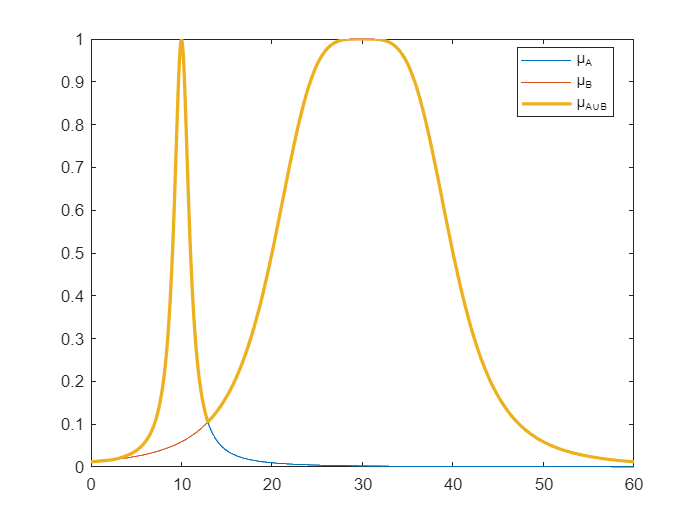

mu_A = 1./(1 + (domain - 10).^2);
plot(domain, mu_A);
hold on
plot(domain, mu_B);
hold on
plot(domain, max(mu_A, mu_B), 'LineWidth', 2);
legend('\mu_A', '\mu_B', '\mu_{A\cupB}', 'Location','best');
hold off

We can see from the plot that this is not the case. For further confirmation, we can check to see if there exists some $x$ for which $max(\mu_A(x), \mu_B(x)) \neq \mu_B(x)$or alternatively, $\mu_B(x) < \mu_A(x)$:

sum(mu_B < mu_A)

ans = 105

As we can see, from our 600 samples, 105 of them satisfy $\mu_B(x) < \mu_A(x)$ and therefore $A \subseteq\not B$.

### H. Union and Intersection of A and B:

Union: $A \cup B = \{(x, \mu_\cup(x)) | \mu_\cup(x) = max(\mu_A(x), \mu_B(x))\}$

plot(domain, mu_A);
hold on
plot(domain, mu_B);
hold on
plot(domain, max(mu_A, mu_B), 'LineWidth', 2);
legend('\mu_A', '\mu_B', '\mu_{A\cupB}', 'Location','best');
hold off

Intersection: $A \cap B = \{(x, \mu_\cup(x)) | \mu_\cup(x) = min(\mu_A(x), \mu_B(x))\}$

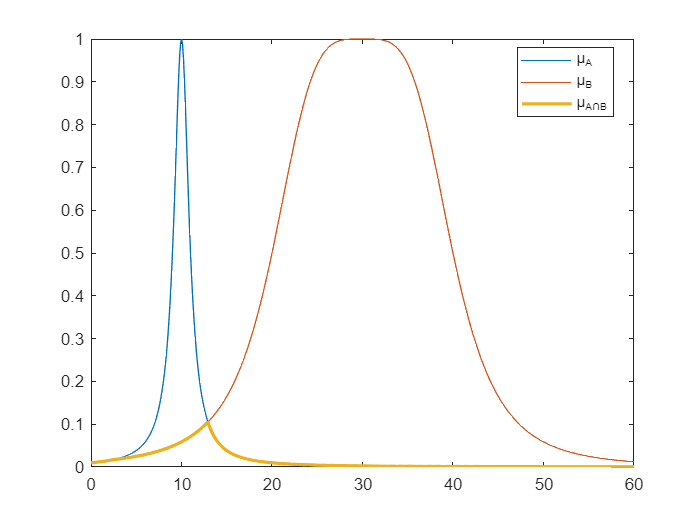

plot(domain, mu_A);
hold on
plot(domain, mu_B);
hold on
plot(domain, min(mu_A, mu_B), 'LineWidth', 2);
legend('\mu_A', '\mu_B', '\mu_{A\capB}', 'Location','best');
hold off

## Problem 4

We are to prove the following:


$$A \cap (B \cup C) = (A\cap B) \cup (A \cap C)$$


We will write out the definition of $A \cap (B \cup C)$ and $(A\cap B) \cup (A \cap C)$:


$$A \cap (B \cup C) = \{(x, \mu(x))| x\in X, \mu(x) = min\{\mu_A(x), max\{\mu_B(x), \mu_C(x)\}\}\}$$



$$(A\cap B) \cup (A \cap C) = \{(x, \mu(x))| x\in X, \mu(x) = max\{min\{\mu_A(x), \mu_B(x)\}, min\{\mu_A(x), \mu_C(x)\}\}\}$$


Now $\forall x \in X$:

### 1. If $\mu_B(x) \ge \mu_C(x)$:


$$A \cap (B \cup C) = \{(x, \mu(x))| x\in X, \mu(x) = min\{\mu_A(x), \mu_B(x)\}\}$$


#### 1.1. If $\mu_B(x) \ge \mu_A(x)$:


$$A \cap (B \cup C) = \{(x, \mu(x))| x\in X, \mu(x) = \mu_A(x)\}$$



$$(A\cap B) \cup (A \cap C) = \{(x, \mu(x))| x\in X, \mu(x) = max\{\mu_A(x), min\{\mu_A(x), \mu_C(x)\}\}\}$$


but we know that $max\{\mu_A(x), min\{\mu_A(x), \mu_C(x)\}\} = \mu_A(x)$because:

- 
$$\mu_A(x) \ge \mu_C(x) \rightarrow min\{\mu_A(x), \mu_C(x)\} = \mu_C(x) \rightarrow max\{\mu_A(x), min\{\mu_A(x), \mu_C(x)\}\} = max\{\mu_A(x), \mu_C(x)\} = \mu_A(x)$$


- 
$$\mu_A(x) < \mu_C(x) \rightarrow min\{\mu_A(x), \mu_C(x)\} = \mu_A(x) \rightarrow max\{\mu_A(x), min\{\mu_A(x), \mu_C(x)\}\} = max\{\mu_A(x), \mu_A(x)\} = \mu_A(x)$$


so,


$$(A\cap B) \cup (A \cap C) = \{(x, \mu(x))| x\in X, \mu(x) = \mu_A(x)\} = A \cap (B \cup C)$$


#### 1.2. If $\mu_B(x) < \mu_A(x)$:


$$A \cap (B \cup C) = \{(x, \mu(x))| x\in X, \mu(x) = \mu_B(x)\}$$



$$(A\cap B) \cup (A \cap C) = \{(x, \mu(x))| x\in X, \mu(x) = max\{\mu_B(x), min\{\mu_A(x), \mu_C(x)\}\}\}$$


But we know that $\mu_A(x) > \mu_B(x) \ge \mu_C(x)$ so,


$$max\{\mu_B(x), min\{\mu_A(x), \mu_C(x)\}\} = max\{\mu_B(x), \mu_C(x)\} = \mu_B(x)$$


and,


$$(A\cap B) \cup (A \cap C) = \{(x, \mu(x))| x\in X, \mu(x) = \mu_B(x)\} = A \cap (B \cup C)$$


### 2. If $\mu_B(x) < \mu_C(x)$:


$$A \cap (B \cup C) = \{(x, \mu(x))| x\in X, \mu(x) = min\{\mu_A(x), \mu_C(x)\}\}$$


#### 2.1. If $\mu_C(x) \ge \mu_A(x)$:


$$A \cap (B \cup C) = \{(x, \mu(x))| x\in X, \mu(x) = \mu_A(x)\}$$



$$(A\cap B) \cup (A \cap C) = \{(x, \mu(x))| x\in X, \mu(x) = max\{min\{\mu_A(x), \mu_B(x)\}, \mu_A(x)\}\}$$


but we know that following the exact same reasoning as* (1.1)*, $max\{min\{\mu_A(x), \mu_B(x)\}, \mu_A(x)\} = \mu_A(x)$and therefore


$$(A\cap B) \cup (A \cap C) = \{(x, \mu(x))| x\in X, \mu(x) = \mu_A(x)\} = A \cap (B \cup C)$$


#### 2.2. If $\mu_C(x) < \mu_A(X)$:


$$A \cap (B \cup C) = \{(x, \mu(x))| x\in X, \mu(x) = \mu_C(x)\}$$



$$(A\cap B) \cup (A \cap C) = \{(x, \mu(x))| x\in X, \mu(x) = max\{min\{\mu_A(x), \mu_B(x)\}, \mu_C(x)\}\}$$


But we know that $\mu_A(x) > \mu_C(x) > \mu_B(x)$ so,


$$max\{min\{\mu_A(x), \mu_B(x)\}, \mu_C(x)\} = max\{\mu_B(x), \mu_C(x)\} = \mu_C(x)$$


and,

$(A\cap B) \cup (A \cap C) = \{(x, \mu(x))| x\in X, \mu(x) =\mu_C(x)\} = A \cap (B \cup C)$.

## Problem 5

**The union of two convex fuzzy sets is not necessarily convex.** Here is a counterexample:

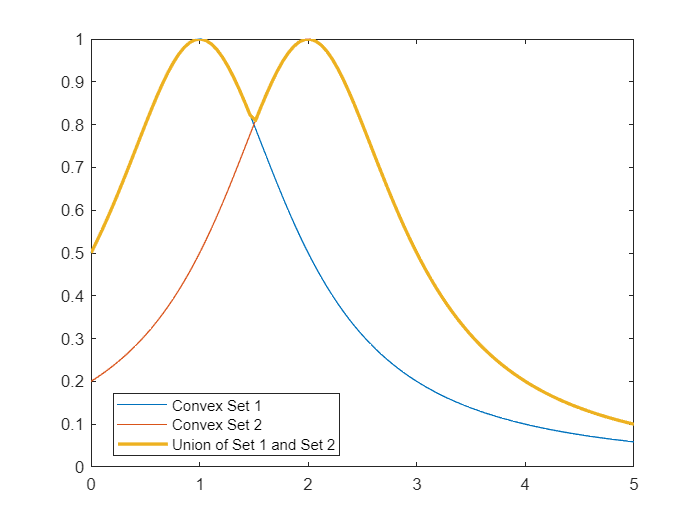

domain_5 = linspace(0,5);
mu_convex_1 = 1./(1 + (domain_5 - 1).^2);
mu_convex_2 = 1./(1 + (domain_5 - 2).^2);
plot(domain_5, mu_convex_1);
hold on
plot(domain_5, mu_convex_2);
hold on
plot(domain_5, max(mu_convex_1, mu_convex_2), 'LineWidth',2);
legend('Convex Set 1', 'Convex Set 2', 'Union of Set 1 and Set 2', 'Location','best');
hold off

As we can see in this counterexample, the union is clearly not convex although both original sets are.

However,** the intersection of two fuzzy convex sets is always convex. **

*Proof:*

Let's say we have two convex fuzzy sets $A$ and $B$ defined over $x\in X$. By definition of convexity:


$$\forall x_1, x_2 \in X, \lambda \in [0, 1]: \mu_A(\lambda x_1 + (1 - \lambda)x_2) \ge min\{\mu_A(x_1),\mu_A(x_2)\}
$$



$$\forall x_1, x_2 \in X, \lambda \in [0, 1]: \mu_B(\lambda x_1 + (1 - \lambda)x_2) \ge min\{\mu_B(x_1),  \mu_B(x_2)\}$$


Without loss of generality we will assume $x_1 < x_2$. To prove the convexity of $A\cap B$ we need to prove:


$$\forall x_1, x_2 \in X, \lambda \in [0, 1]: \mu_{A\cap B}(\lambda x_1 + (1 - \lambda)x_2) \ge min\{\mu_{A\cap B}(x_1),  \mu_{A\cap B}(x_2)\} \\= min\{min\{\mu_A(x_1), \mu_B(x_1)\}, min\{\mu_A(x_2), \mu_B(x_2)\}\} =min\{\mu_A(x_1), \mu_B(x_1), \mu_A(x_2), \mu_B(x_2)\}$$


or


$$min\{\mu_A(\lambda x_1 + (1 - \lambda)x_2), \mu_B(\lambda x_1 + (1 - \lambda)x_2)\} \ge min\{\mu_A(x_1), \mu_B(x_1), \mu_A(x_2), \mu_B(x_2)\}$$


but this must be true because,


$$x_1 \le \lambda x_1 + (1-\lambda)x_2 \le x_2$$


and therefore, from convexity of $A$ we have,


$$\mu_A(\lambda x_1 + (1-\lambda)x_2) \ge min\{\mu_A(x_1), \mu_A(x_2)\} (I)$$


and from convexity of $B$ we have,


$$\mu_B(\lambda x_1 + (1-\lambda)x_2) \ge min\{\mu_B(x_1), \mu_B(x_2)\} (II)
$$


and finally from $(I)$ and $(II)$,


$$min\{\mu_A(\lambda x_1 + (1 - \lambda)x_2), \mu_B(\lambda x_1 + (1 - \lambda)x_2)\} \ge min\{\mu_A(x_1), \mu_B(x_1), \mu_A(x_2), \mu_B(x_2)\}$$


which is what we wanted.

## Problem 6

Pairwise union and intersection of fuzzy sets, F, G and H: (We assume a shared domain $D = [0, 20]$)

shared_domain = linspace(0, 20);
mu_F = shared_domain ./ (shared_domain + 2);
mu_G = 1./(1 + 10*(shared_domain - 2).^2);
mu_H = 2.^(-shared_domain);

### 1. F and G:

#### 1.1. Union:

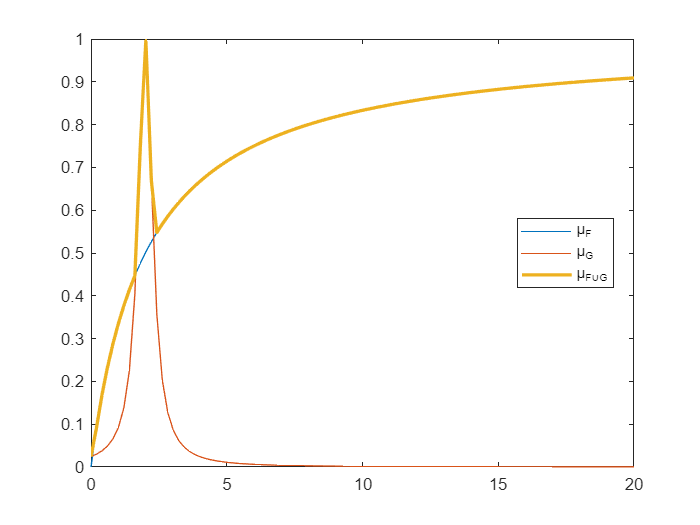

plot(shared_domain, mu_F);
hold on
plot(shared_domain, mu_G);
hold on
plot(shared_domain, max(mu_F, mu_G), 'LineWidth', 2);
legend('\mu_F', '\mu_G', '\mu_{F\cupG}', 'Location','best');
hold off

#### 1.2. Intersection:

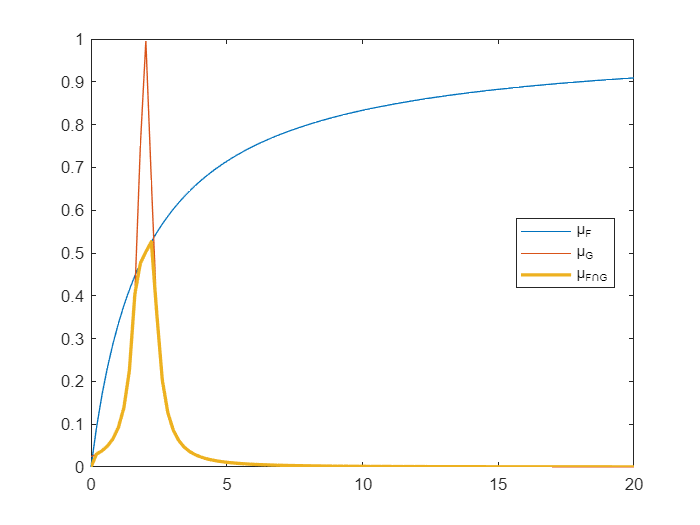

plot(shared_domain, mu_F);
hold on
plot(shared_domain, mu_G);
hold on
plot(shared_domain, min(mu_F, mu_G), 'LineWidth', 2);
legend('\mu_F', '\mu_G', '\mu_{F\capG}', 'Location','best');
hold off

### 2. G and H:

#### 2.1. Union:

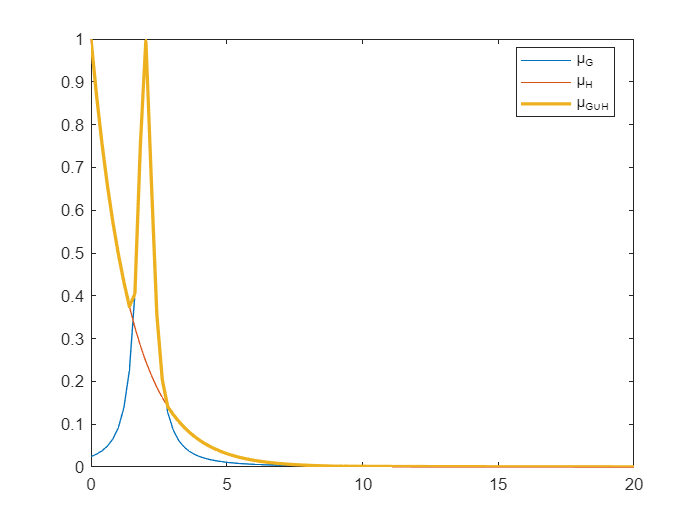

plot(shared_domain, mu_G);
hold on
plot(shared_domain, mu_H);
hold on
plot(shared_domain, max(mu_G, mu_H), 'LineWidth', 2);
legend('\mu_G', '\mu_H', '\mu_{G\cupH}', 'Location','best');
hold off

#### 2.2. Intersection:

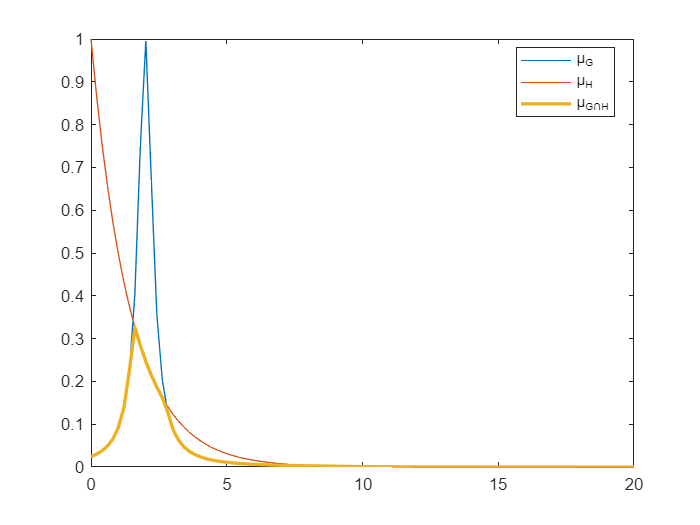

plot(shared_domain, mu_G);
hold on
plot(shared_domain, mu_H);
hold on
plot(shared_domain, min(mu_G, mu_H), 'LineWidth', 2);
legend('\mu_G', '\mu_H', '\mu_{G\capH}', 'Location','best');
hold off

### 3. F and H:

#### 3.1. Union:

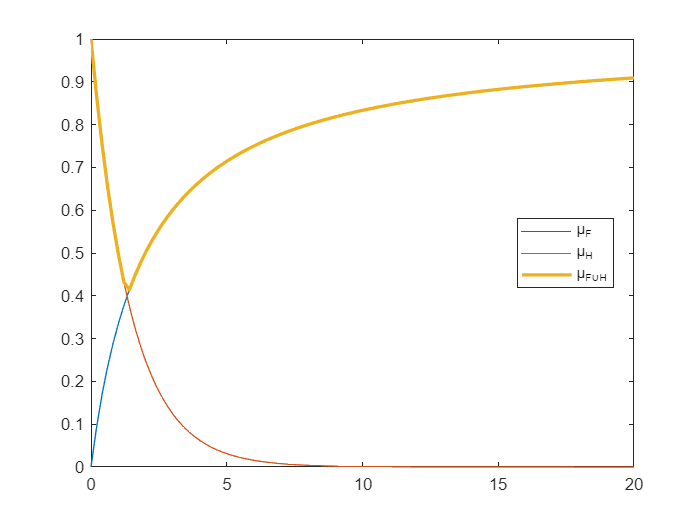

plot(shared_domain, mu_F);
hold on
plot(shared_domain, mu_H);
hold on
plot(shared_domain, max(mu_F, mu_H), 'LineWidth', 2);
legend('\mu_F', '\mu_H', '\mu_{F\cupH}', 'Location','best');
hold off

#### 3.2. Intersection:

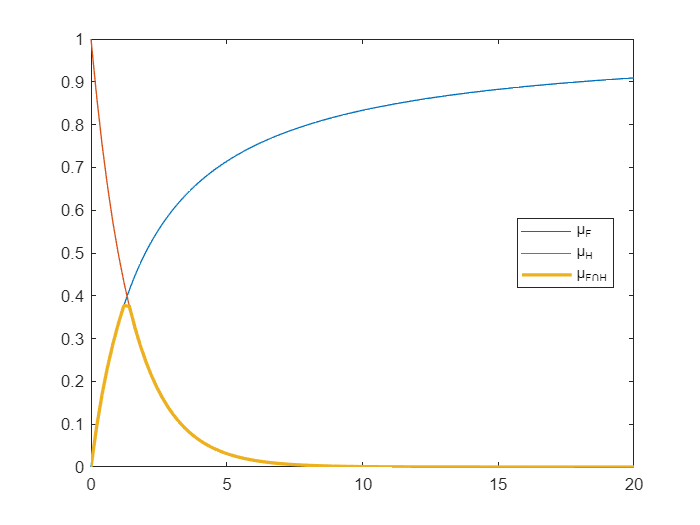

plot(shared_domain, mu_F);
hold on
plot(shared_domain, mu_H);
hold on
plot(shared_domain, min(mu_F, mu_H), 'LineWidth', 2);
legend('\mu_F', '\mu_H', '\mu_{F\capH}', 'Location','best');
hold off

## Problem 7


$$N_w(a) = (1 - a^w)^\frac{1}{w}$$


### 1. Boundary Conditions:


$$N_w(0) = (1 - 0^w)^\frac{1}{w} = 1$$



$$N_w(1) = (1 - 1^w)^\frac{1}{w} = 0$$


### 2. Continuity:

Instead of a mathematical proof we will resort to a visual one, we will draw $N_w(a)$ for two values of $w \in {0.5, 2}$.

By observing that function has no holes or breaks in it, we can deduce that it is continuous over $[0, 1]$.

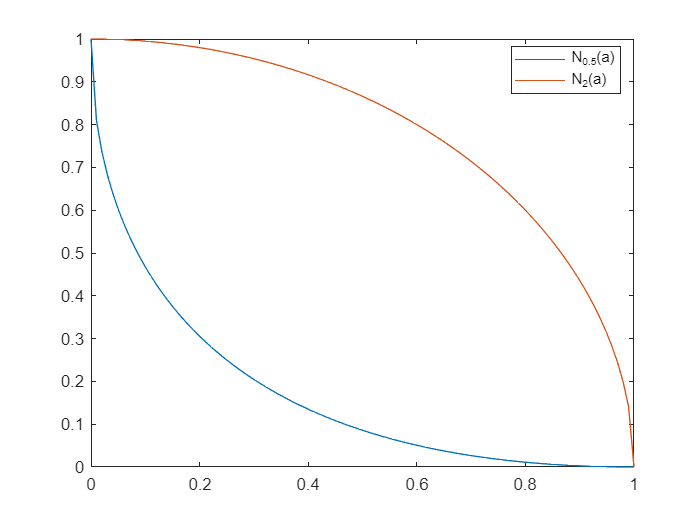

w_1 = 0.5;
w_2 = 2;
domain_yager = linspace(0,1);
N_w_1 = (1 - domain_yager.^w_1).^(1/w_1);
N_w_2 = (1 - domain_yager.^w_2).^(1/w_2);
plot(domain_yager, N_w_1);
hold on
plot(domain_yager, N_w_2);
legend('N_{0.5}(a)', 'N_2(a)', 'Location','best');
hold off

As we can see, the Yager complement is continuous over $[0, 1]$.

#### 3. Monotonic Decreasing:

$\forall a, b \in [0, 1]$ if $a < b$, 


$$a^w < b^w \rightarrow -a^w > -b^w \rightarrow 1 - a^w > 1 - b^w$$


for $w>0$ (and $\frac{1}{w} > 0$):

$(1 - a^w)^\frac{1}{w} > (1 - b^w)^\frac{1}{w} \rightarrow N_w(a) > N_w(b)$.

### 4. Involution:

$N_w(N_w(a)) = (1 - ((1 - a^w)^\frac{1}{w})^w)^\frac{1}{w} = (1 - (1 - a^w))^\frac{1}{w}
= (1 - 1 + a^w)^\frac{1}{w} = (a^w)^\frac{1}{w} = a$.

## Problem 8

Plot of $\mu_M(x; a, x_0) = \frac{1}{1 + e^{a(x-x_0)}}$ for $a={-2,-1,1,2}$ and $x_0 = 5$:

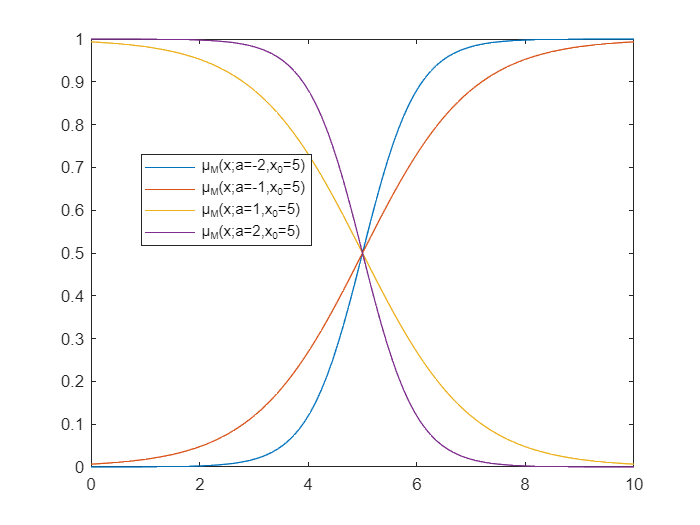

domain_m = linspace(0, 10);
x_0 = 5;
a_1 = -2;
a_2 = -1;
a_3 = 1;
a_4 = 2;
mu_M_1 = 1./(1 + exp(a_1.*(domain_m - x_0)));
mu_M_2 = 1./(1 + exp(a_2.*(domain_m - x_0)));
mu_M_3 = 1./(1 + exp(a_3.*(domain_m - x_0)));
mu_M_4 = 1./(1 + exp(a_4.*(domain_m - x_0)));
plot(domain_m, mu_M_1);
hold on
plot(domain_m, mu_M_2);
hold on
plot(domain_m, mu_M_3);
hold on
plot(domain_m, mu_M_4);
legend('\mu_M(x;a=-2,x_0=5)','\mu_M(x;a=-1,x_0=5)',...
    '\mu_M(x;a=1,x_0=5)','\mu_M(x;a=2,x_0=5)','Location','best');
hold off